## Boas práticas

clc;                    % limpa a tela
clear all;              % limpa as variáveis
close all;              % fecha as figuras


## Leitura do RQUIVO .WAV - AUDIOREAD

[y, fs] = audioread('Analise_Audio_Wav\Audio01.wav');

fs

fs = 44100

ts     = 1/fs

ts = 2.2676e-05

y

y =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


nPontos = length(y)

nPontos = 786816


vFinal  = (nPontos -1) * ts

vFinal = 17.8416

tempo   = (linspace(0, vFinal, nPontos))

tempo =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


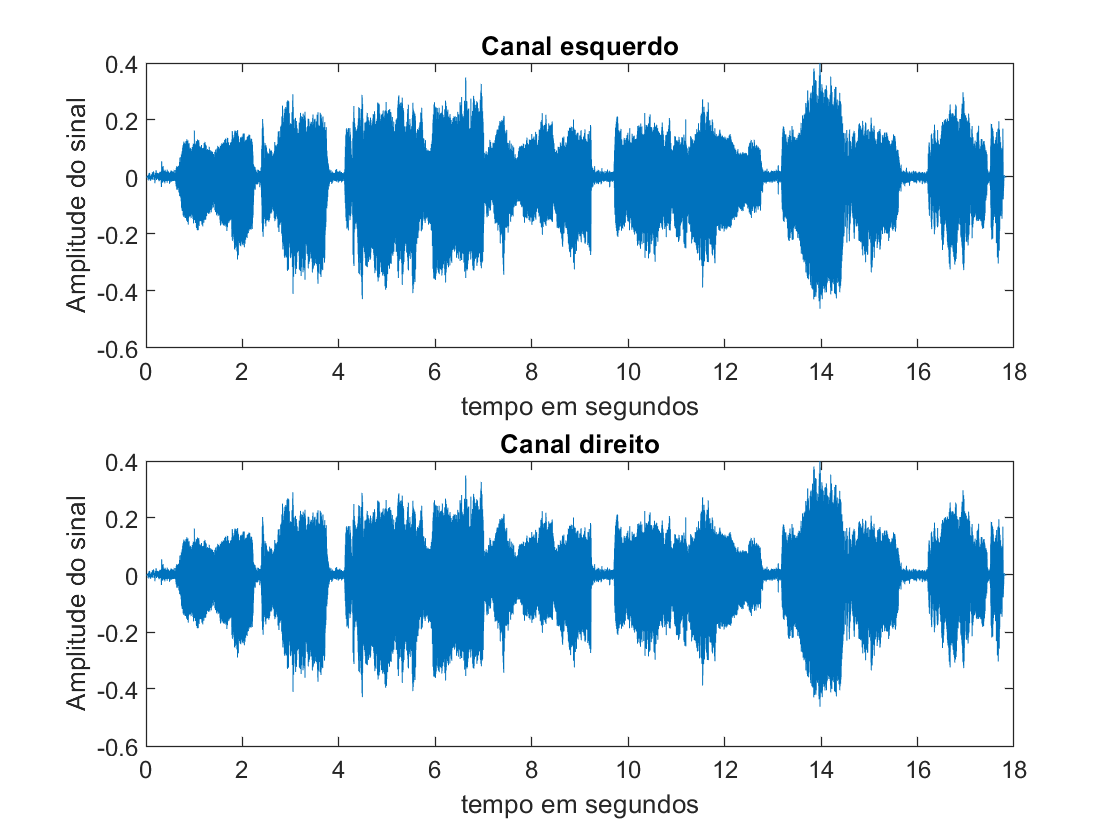


figure(1);
subplot(2,1,1);
plot(tempo, y(:,1));
xlabel('tempo em segundos')
ylabel('Amplitude do sinal')
title('Canal esquerdo')

subplot(2,1,2);
plot(tempo, y(:,2));
xlabel('tempo em segundos')
ylabel('Amplitude do sinal')
title('Canal direito')

## Ouvir um arquivo .wav

% sound(y, fs);
fy = fftshift(fft(y))

fy = 	1.0e+03 *

   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0000 - 0.0000i  -0.0000 - 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0000 - 0.0000i  -0.0000 - 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 - 0.0000i   0.0000 - 0.0000i
  -0.0000 - 0.0000i  -0.0000 - 0.0000i


## Visualizar a FFT e interpretar

frequencia = linspace(-fs/2, fs/2, nPontos) % eixo x

frequencia = 	1.0e+04 *

   -2.2050   -2.2050   -2.2050   -2.2050   -2.2050   -2.2050   -2.2050   -2.2050   -2.2050   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2049   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2048   -2.2047   -2.2047   -2.2047   -2.2047   -2.2047


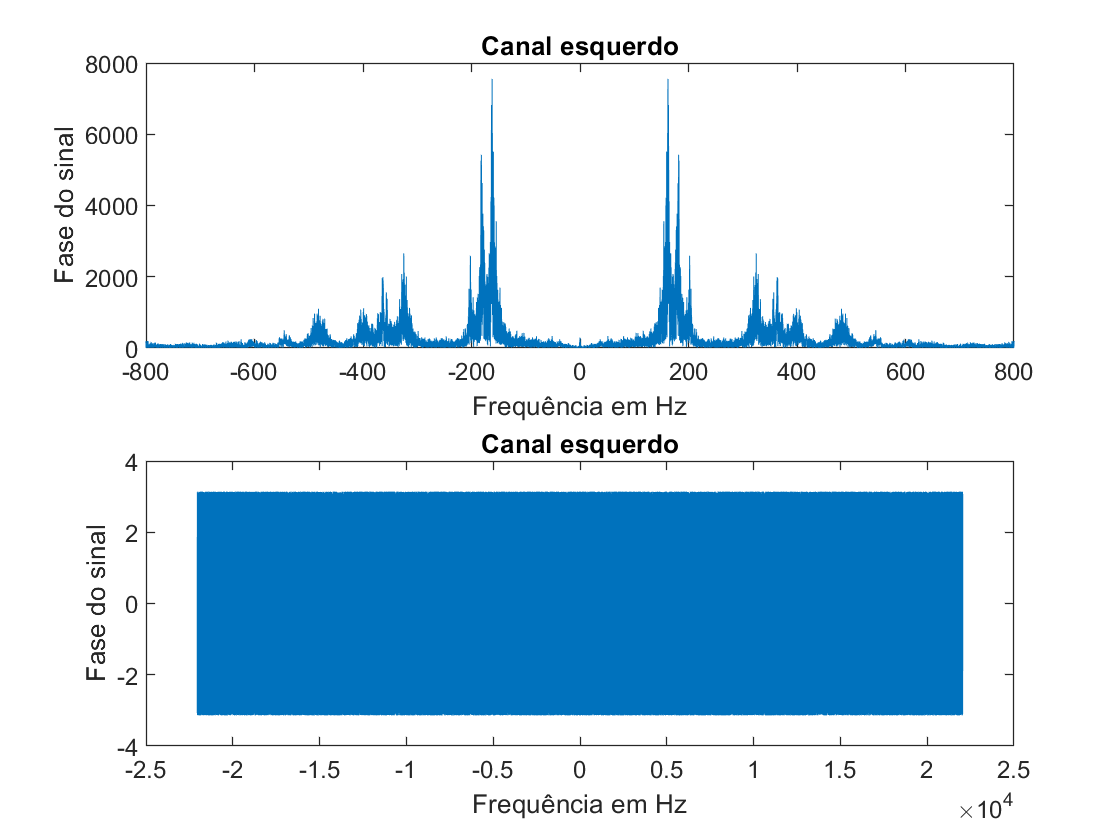



figure(2);
subplot(2,1,1);
plot(frequencia, abs(fy(:,1)))
xlabel('Frequência em Hz')
ylabel('Fase do sinal')
title('Canal esquerdo')

subplot(2,1,1)
xlim([-800 800]);   % ZOOM
ylim([0 8000]);


subplot(2,1,2);
plot(frequencia,angle(fy(:,1)))
xlabel('Frequência em Hz')
ylabel('Fase do sinal')
title('Canal esquerdo')